# Machine Learning From Coursera

Exercise 2 -Classification with Regularization

clear all;close all;clc
data=load("ex2data2.txt");
x=data(:,[1,2]);
y=data(:,3);
fprintf("First 5 examples of data:\n");

First 5 examples of data:


fprintf("x=[%.4f %.4f],y=[%.f]\n",[x(1:5,:) y(1:5,:)]');

x=[0.0513 0.6996],y=[1]
x=[-0.0927 0.6849],y=[1]
x=[-0.2137 0.6923],y=[1]
x=[-0.3750 0.5022],y=[1]
x=[-0.5132 0.4656],y=[1]


We have to make a classification model based on the data. We plot the available data.In this example, we cannot use separated line to make a decision boundary.Instad ,we use feature mapping to fit the data.

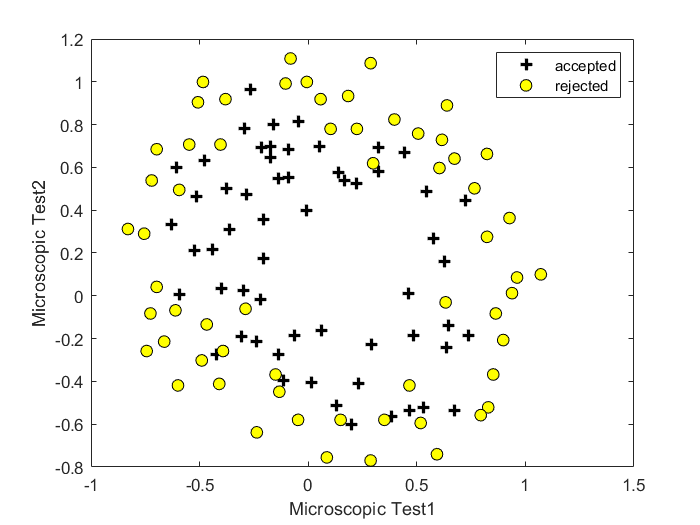

%plot the data
pos=find(y==1);neg=find(y==0);
plot(x(pos,1),x(pos,2),'k+','LineWidth',2,'MarkerSize',7);
hold on
plot(x(neg,1),x(neg,2),'ko','MarkerFaceColor','y','MarkerSize',7);
hold off
xlabel('Microscopic Test1');
ylabel('Microscopic Test2');
legend('accepted','rejected');

## Feature Mapping

One way to fit the data better is to create more features from each data point. In the provided function mapFeature, we will map the features into all polynomial terms of x1 and x2 up to sixth power.

                                                    mapFeature(x)=$\left\lbrack \begin{array}{c}
1\\
x_1 \\
x_2 \\
x_1^2 \\
x_1 x_2 \\
x_2^2 \\
x_1^3 \\
\ldotp \ldotp \\
x_2^6 
\end{array}\right\rbrack$

As a result of this mapping, our vecotr of two features has been transformed into a 28-dimensional vector. A logistic regression classifier tranied on this higher-dimension feature vector will have a more complex decision boundary and will appear non-linear when drawn in our 2-dimensional

## Cost function and Gradient

Regularized cost function in logistic regression is


$$J\left(\theta \right)=\frac{1}{m}\sum_{i=1}^m \left\lbrack -y^{\left(i\right)} \log \left(h_{\theta } \left(x^{\left(i\right)} \right)\right)-\left(1-y^{\left(i\right)} \right)\log \left(1-h_{\theta } \left(x^{\left(i\right)} \right)\right)+\frac{\lambda }{2m}\sum_{j=1}^n \theta_j^2 \right\rbrack$$


The gradient of the cost funcition is a vector where the $j^{\textrm{th}}$element is defined as follows:


$$\frac{\partial }{\partial \theta_0 }J\left(\theta \right)=\frac{1}{m}\sum_{i=1}^m \left(h_{\theta } \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\textrm{for}\;j=0$$



$$\frac{\partial }{\partial \theta_j }J\left(\theta \right)=\left(\frac{1}{m}\sum_{i=1}^m \left(h_{\theta } \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \right)+\frac{\lambda }{m}\theta_j \;\textrm{for}\;j\ge 1$$


%feature mapping
X=mapFeature(x(:,1),x(:,2));
initial_theta=zeros(size(X,2),1);
m=length(y);

[J,Gradient]=cost_gradient(initial_theta,X,y,m,1);
fprintf("Cost at Initial Theta: J= %.3f",J);

Cost at Initial Theta: J= 0.693

%test with all ones theta and lambda =10
test_theta = ones(size(X,2),1);
[J,Gradient]=cost_gradient(test_theta,X,y,m,10);
fprintf("Cost at tested Theta: J= %.3f",J);

Cost at tested Theta: J= 3.165

## Regularization and Accuracy

%set options for fminunc
options = optimset('GradObj', 'on', 'MaxIter', 400);
lambda=1;
[theta, J,exit_flag] = fminunc(@(t)(cost_gradient(t, X, y,m,lambda)), initial_theta, options);


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


fprintf('Cost at theta found by fminunc: %.3f\n', J);

Cost at theta found by fminunc: 0.529


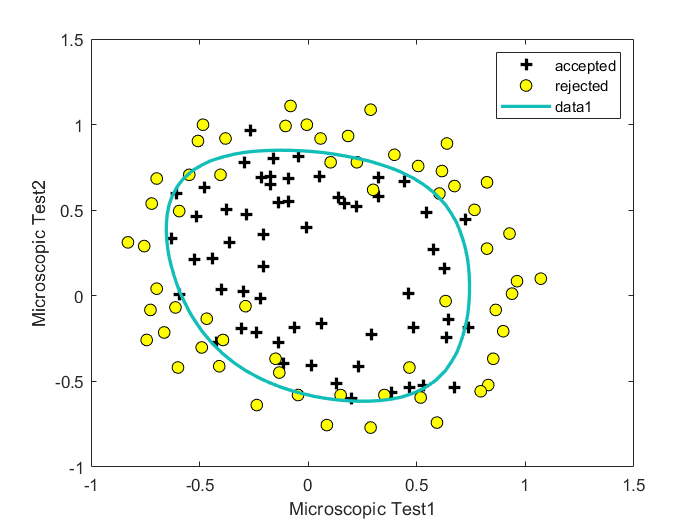

plotDecisionBoundary(theta,X,y)

Decision Boundary of Logistic Regression is the set of all points x that satisfy:

P(y=1|x)=P(y=0|x)=1/2

Given: $P\left(y=1\left|x\right.\right)$=$\frac{1}{1+e^{-\theta^t X} }$     where $\theta =\left(\theta_0 +\theta_1 +\ldotp \ldotp \ldotp \theta_{n+1} \right)$and $x=\left(1,x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n \right)$


$$\frac{1}{1+e^{{-\theta }^t X} }=\frac{1}{2}$$



$$\theta^{-T} X=0$$


$\left(\theta_0 +\theta_1 x_1 +\theta_{n+1} x_n \right)$=0

For two dimensional data,

$\left(\theta_0 +\theta_1 x_1 +\theta_2 x_2 \right)$=0


$$x_1 =-\frac{\theta_0 }{\theta_1 }-\frac{\theta_2 }{\theta_1 }x_2 \;;$$
 
$$x_1 =-\frac{\theta_0 }{\theta_1 }-\frac{\theta_2 }{\theta_1 }x_2$$


In matlab, $\theta \;\textrm{starts}\;\textrm{from}\;1$, so $x_1 =-\frac{\theta_1 }{\theta_2 }-\frac{\theta_3 }{\theta_2 }x_2 \;;$ $x_1 =-\frac{\theta_1 }{\theta_2 }-\frac{\theta_3 }{\theta_2 }x_2$

## Prediction Accuracy

% to compute accuracy on our training set
p=Predict(theta,X);
fprintf("Accuracy on our training set: %.f",mean(double(p==y))*100);

Accuracy on our training set: 83

 function out=mapFeature(X1,X2)  
%  Returns a new feature array with more features, comprising of 
%   X1, X2, X1.^2, X2.^2, X1*X2, X1*X2.^2, etc.
degree = 6;
out = ones(size(X1(:,1)));
for i = 1:degree
    for j = 0:i
        out(:, end+1) = (X1.^(i-j)).*(X2.^j);
    end
end

end
  
function plotDecisionBoundary(theta, X, y)
hold on
if size(X, 2) <= 3
    % Only need 2 points to define a line, so choose two endpoints
    plot_x = [min(X(:,2))-2,  max(X(:,2))+2];

    % Calculate the decision boundary line
    plot_y = (-1./theta(3)).*(theta(2).*plot_x + theta(1));

    % Plot, and adjust axes for better viewing
    plot(plot_x, plot_y)    
    % Legend, specific for the exercise
    legend('Admitted', 'Not admitted', 'Decision Boundary')
    axis([30, 100, 30, 100])
else
    % Here is the grid range
    u = linspace(-1, 1.5, 50);
    v = linspace(-1, 1.5, 50);
    z = zeros(length(u), length(v));
    % Evaluate z = theta*x over the grid
    for i = 1:length(u)
        for j = 1:length(v)
            z(i,j) = mapFeature(u(i), v(j))*theta;
        end
    end
    z = z'; % important to transpose z before calling contour

    % Plot z = 0
    % Notice you need to specify the range [0, 0]
    contour(u, v, z, [0, 0], 'LineWidth', 2)
end
hold off
end

function s=sigmoid(z)
s=zeros(size(z));
s=1./(1+exp(-z));
end

function [J,Gradient]=cost_gradient(theta,X,y,m,lambda)
h=sigmoid(X*theta);
reg=(lambda/(2*m))*theta(2:end,:)'*theta(2:end,:);
J=(1/m)*sum(-y.*log(h)-(1-y).*log(1-h))+reg;

Gradient=zeros(size(theta,1),1);
Gradient(1)=(1/m)*sum((h-y).*X(:,1));
for i=2:size(Gradient)
  Gradient(i)=((1/m)*sum((h-y).*X(:,i)))'+(lambda/m)*theta(i);
end
end

function [predict]=Predict(theta,X)
 m=size(X,1);
 predict=zeros(m,1);
 predict=round(sigmoid(X*theta));
 end       
